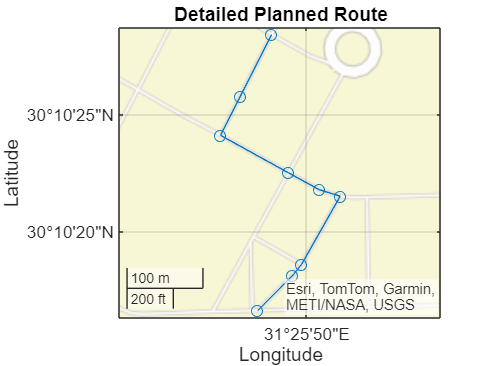

startPoint = '30.171360, 31.429886'; 
endPoint = '30.174631, 31.430075';   

apiKey = 'AkcTX5hM23b-cGXjH8ba9sl0MA3eSz37TcVjVCSwu3P9RtndcIfgEjdohxGsGDvr';

url = sprintf('http://dev.virtualearth.net/REST/V1/Routes/Driving?wp.0=%s&wp.1=%s&routePathOutput=Points&key=%s', startPoint, endPoint, apiKey);

response = webread(url);

routePoints = response.resourceSets(1).resources(1).routePath.line.coordinates;

latitudes = [];
longitudes = [];


for i = 1:size(routePoints, 1)
    latitudes = [latitudes; routePoints(i, 1)];
    longitudes = [longitudes; routePoints(i, 2)];
end

figure;
geoplot(latitudes, longitudes, '-o');
title('Detailed Planned Route');
geobasemap('streets');